# Understanding the assumptions

First, we load the data

data=select_and_normalize('taiwan');
tr=data.tr;
te=data.te;
y_tr=data.y_tr;
y_te=data.y_te;

First, we run a simple OLS model and plot the residuals.    

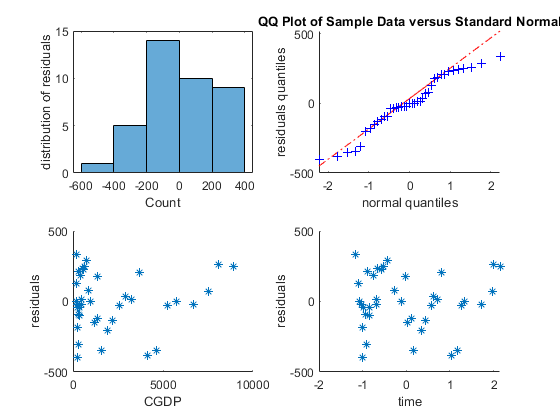

model_all = ols(tr,y_tr);
plot_residuals(model_all,tr,y_tr);

In this plot, we do not see a clear pattern but we can still observe higher variability when CGDP grows (residuals are more concentrated around 0 when CGDP is low). Therefore, we suspect the homescedasticiy assumption not to be valid. Let's test that using a Breush Pagen Test. 

Breusch Pagan Test

[BP_stat,BP_crit,H] = Breusch_Pagan_test(tr,model_all.residuals,0.95);
H

H = 1

Thefore, we reject the homescedascity assumption. The next natural step would be to look at a more general version of least square where the homoscedasticity assumption is not required to be valid. FGLS constiute the alternative we are looking for. 

It is important to deal with this issue for  the following reasons: 

1) ordinary least squares no longer produces the unbiased/constistents estimators  

2) standard errors computed using least squares can be incorrect and misleading. 

FGLS

model_FGLS = FGLS(tr,y_tr);
% Breush Pagan on FGLS
[BP_stat_FGLS,BP_crit_FGLS,H_FGLS] = Breusch_Pagan_test(tr,model_FGLS.residuals,0.95);
plot_residuals(model_all,tr,y_tr);

H_FGLS

H_FGLS = 1

If we clearly see a drop in the value of the BP test, the FGLS is still not powerfull enough to caputre all the heterscedasticity assumption in our dataset.

%beta = fgls(tr(:,2:end),y_tr);
%library_model =  compute_statistics(tr,y_tr,beta); 
%[BP_stat_FGLS_2,BP_crit_FGLS_2,H_FGLS_2] = Breusch_Pagan_test(tr,library_model.residuals,0.95);
%plot_residuals(library_model,tr,y_tr);
%H_FGLS_2
model_FGLS_3 = FGLS(tr,y_tr,"hetero");

A transformation was applied to X, use tX in the output


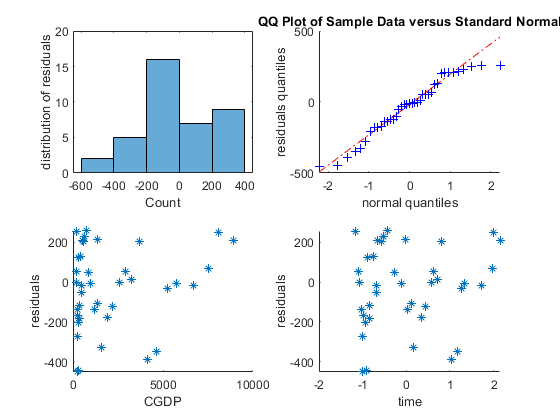

[BP_stat_FGLS_3,BP_crit_FGLS_3,H_FGLS_3] = Breusch_Pagan_test(model_FGLS_3.tX,model_FGLS_3.residuals,0.95);
plot_residuals(model_FGLS_3,tr,y_tr);

H_FGLS_3

H_FGLS_3 = 1

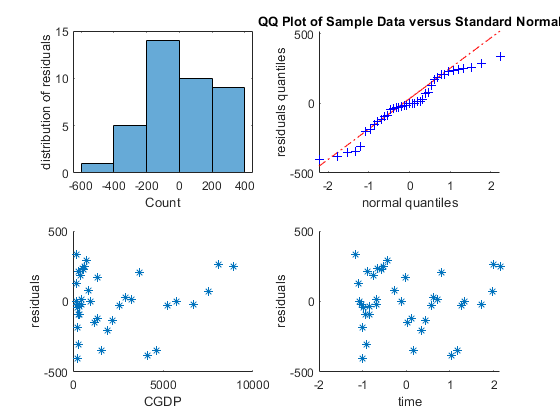

model_FGLS_4 = FGLS(tr,y_tr,"time-series");
[BP_stat_FGLS_4,BP_crit_FGLS_4,H_FGLS_4] = Breusch_Pagan_test(tr,model_FGLS_4.residuals,0.95);
plot_residuals(model_FGLS_4,tr,y_tr);

H_FGLS_4

H_FGLS_4 = 1

## Transformations

We didn't manage to obtain satisfying results using FGLS methods thus we will try a different approach here. We will try to perform a least square on transformations of the inputs. By doing so we hope that impact of the residual heteroscedasticity will be reduced. 

% loglog tranformation : we transforme X and y by applying the log
loglog_model= ols(tr,y_tr,'loglog');

X and y have changed due to log log transformation !


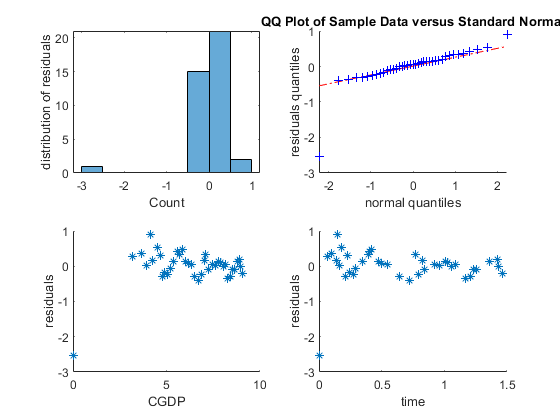

plot_residuals(loglog_model,loglog_model.tX,loglog_model.ty);

% R2 score on test set
%first we transform the test as using the same transformation as the train
%set 
transformed_te  = log_transform(te-min(tr)+1);
transformed_yte = log_transform(y_te-min(y_tr)+1);
% compute the statistics
[loglog_test_result] = test_model(loglog_model.beta,transformed_te,transformed_yte)

loglog_test_result = struct with fields:
                beta: [6×1 double]
              sigma2: 12.6934
          sample_var: [6×6 double]
           std_error: [6×1 double]
                 AIC: 2.8248
                 BIC: 3.0063
                  R2: 0.2307
              adj_R2: -0.7308
                  CI: [6×2 double]
            p_values: [6×1 double]
    significant_test: 0
           residuals: [10×1 double]
                pred: [10×1 double]


% Breusch pagan test
[BP_stat_FGLS_LOGLOG,BP_crit_FGLS_LOGLOG,H_FGLS_LOGLOG] = Breusch_Pagan_test(loglog_model.tX,loglog_model.residuals,0.95);
H_FGLS_LOGLOG

H_FGLS_LOGLOG = 1

% linlog tranformation : we transforme X  by applying the log
linlog_model= ols(tr,y_tr,'linlog');

X has changed due to log transformation


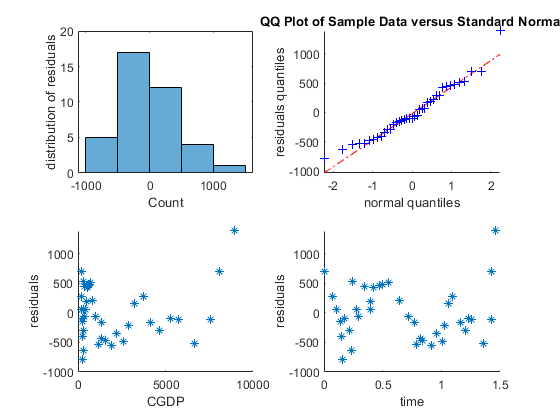

plot_residuals(linlog_model,linlog_model.tX,y_tr);

% R2 score on test set
[loglog_test_result] = test_model(linlog_model.beta,transformed_te,transformed_yte)

loglog_test_result = struct with fields:
                beta: [6×1 double]
              sigma2: 1.1769e+08
          sample_var: [6×6 double]
           std_error: [6×1 double]
                 AIC: 18.8673
                 BIC: 19.0488
                  R2: -7.1325e+06
              adj_R2: -1.6048e+07
                  CI: [6×2 double]
            p_values: [6×1 double]
    significant_test: 0
           residuals: [10×1 double]
                pred: [10×1 double]


% Breusch pagan test
[BP_stat_FGLS_LINLOG,BP_crit_FGLS_LINLOG,H_FGLS_LINLOG] = Breusch_Pagan_test(linlog_model.tX,linlog_model.residuals,0.95);
H_FGLS_LINLOG

H_FGLS_LINLOG = 1

% loglin tranformation : we transforme y  by applying the log
loglin_model= ols(tr,y_tr,'loglin');

y has changed due to log transformation


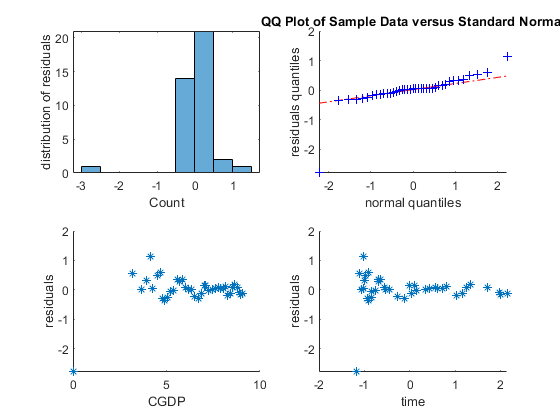

plot_residuals(loglin_model,tr,loglin_model.ty);

% R2 score on test set
[loglog_test_result] = test_model(loglin_model.beta,transformed_te,transformed_yte)

loglog_test_result = struct with fields:
                beta: [6×1 double]
              sigma2: 11.7146
          sample_var: [6×6 double]
           std_error: [6×1 double]
                 AIC: 2.7445
                 BIC: 2.9261
                  R2: 0.2901
              adj_R2: -0.5974
                  CI: [6×2 double]
            p_values: [6×1 double]
    significant_test: 0
           residuals: [10×1 double]
                pred: [10×1 double]


% Breusch pagan test
[BP_stat_LOGLIN,BP_crit_LOGLIN,H_LOGLIN] = Breusch_Pagan_test(tr,loglin_model.residuals,0.95);
H_FGLS_LINLOG

H_FGLS_LINLOG = 1

function [] = plot_residuals(model,X,y)
    figure;
    subplot(2,2,1);
    histogram(model.residuals);
    ylabel('distribution of residuals') ;
    xlabel('Count');
    subplot(2,2,2);
    qqplot(model.residuals);
    ylabel('residuals quantiles') ;
    xlabel('normal quantiles');
    subplot(2,2,3);
    scatter(y,model.residuals,'*');
    ylabel('residuals') ;
    xlabel('CGDP') ;
    subplot(2,2,4);
    scatter(X(:,2),model.residuals,'*');
    ylabel('residuals');
    xlabel('time') ;
end